# Control and Instrumentation Lab Assignment 3

**SWARNENDU PAUL 19EE3FP18**

**Question 4.**

**A.**

**i.**


$$G(s)=\frac{-(s-1)}{(s+1)^2}$$


figure
tf1=zpk(1,[-1,-1],-1)

tf1 =
 
  - (s-1)
  -------
  (s+1)^2
 
Continuous-time zero/pole/gain model.



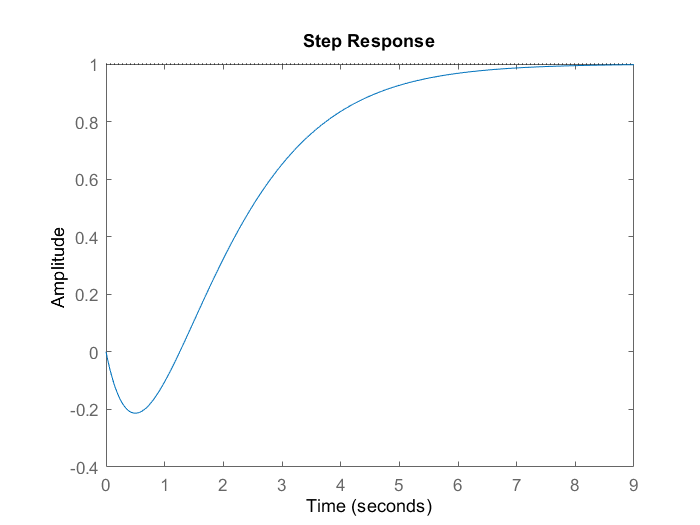

step(tf1)

- Strictly proper

- Initial undershoot

- zero crossing

- **no** overshoot

- 1 positive zero of $G(s)$

- 1 positive zero of $G(s)-G(\infty)$

- 0 positive zero of $G(s)-G(0)$

**ii.**


$$G(s)=\frac{s-1}{(s+1)^2}$$


figure
tf2=zpk(1,[-1,-1],1)

tf2 =
 
   (s-1)
  -------
  (s+1)^2
 
Continuous-time zero/pole/gain model.



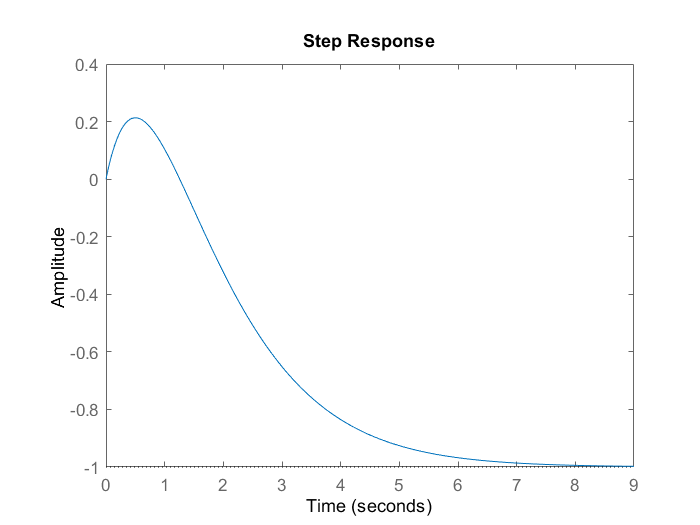

step(tf2)

- Strictly proper

- Initial undershoot

- zero crossing

- **no **negative overshoot

- 1 positive zero of $G(s)$

- 1 positive zero of $G(s)-G(\infty)$

- 0 positive zero of $G(s)-G(0)$

**iii.**


$$G(s)=\frac{(s-1)^2}{(s+1)^2}$$


figure
tf3=zpk([1,1],[-1,-1],1)

tf3 =
 
  (s-1)^2
  -------
  (s+1)^2
 
Continuous-time zero/pole/gain model.



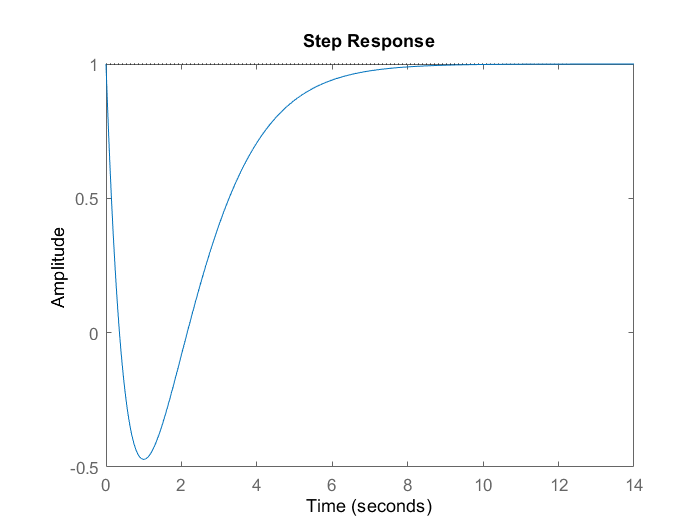

step(tf3)

- Proper

- Initial undershoot

- zero crossing

- **no **overshoot

- 2 positive zeros of $G(s)$

- 0 positive zero of $G(s)-G(\infty)$

- 0 positive zero of $G(s)-G(0)$

**iv.**


$$G(s)=\frac{(s^2-10s+27)}{(s+3)^3}$$


figure
tf4=tf([0,1,-10,27],[1,9,27,27])

tf4 =
 
      s^2 - 10 s + 27
  -----------------------
  s^3 + 9 s^2 + 27 s + 27
 
Continuous-time transfer function.



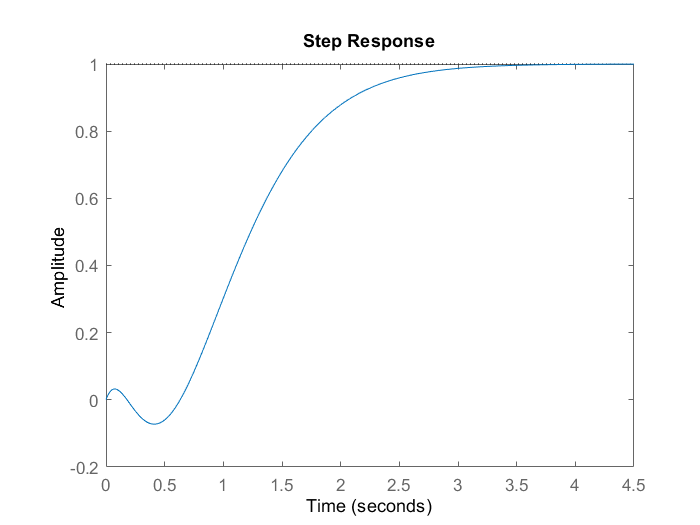

step(tf4)

- Strictly proper

- Initial undershoot

- zero crossing

- **no **overshoot

- 0 positive zero of $G(s)$, 2 complex zeros

- 0 positive zero of $G(s)-G(\infty)$,2 complex zeros

- 0 positive zero of $G(s)-G(0)$, 2 complex zeros

**v.**


$$G(s)=\frac{(2s^2-s+1)}{(s+1)^3}$$


figure
tf5=tf([2,-1,1],[1,3,3,1])

tf5 =
 
      2 s^2 - s + 1
  ---------------------
  s^3 + 3 s^2 + 3 s + 1
 
Continuous-time transfer function.



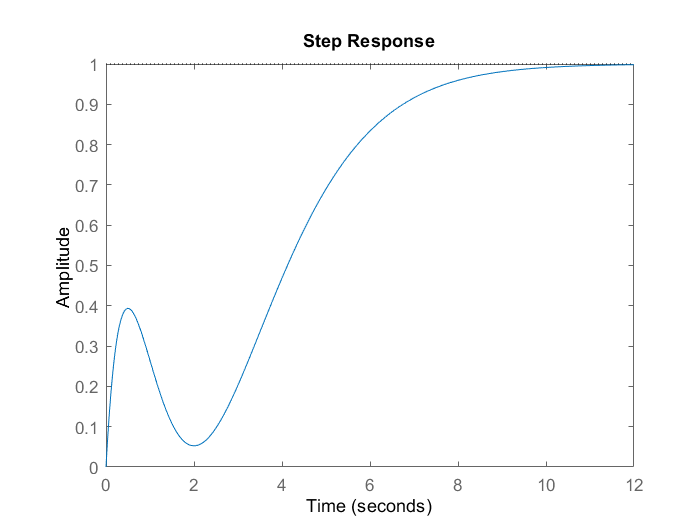

step(tf5)

- Strictly proper

- Initial undershoot

- **no **zero crossing

- **no **overshoot

- 0 positive zero of $G(s)$,2 complex zeros

- 0 positive zero of $G(s)-G(\infty)$,2 complex zeros

- 0 positive zero of $G(s)-G(0)$,2 complex zeros

**vi.**


$$G(s)=\frac{(s^2-s+4)}{(s+1)^3}$$


figure
tf6=tf([1,-1,4],[1,3,3,1])

tf6 =
 
       s^2 - s + 4
  ---------------------
  s^3 + 3 s^2 + 3 s + 1
 
Continuous-time transfer function.



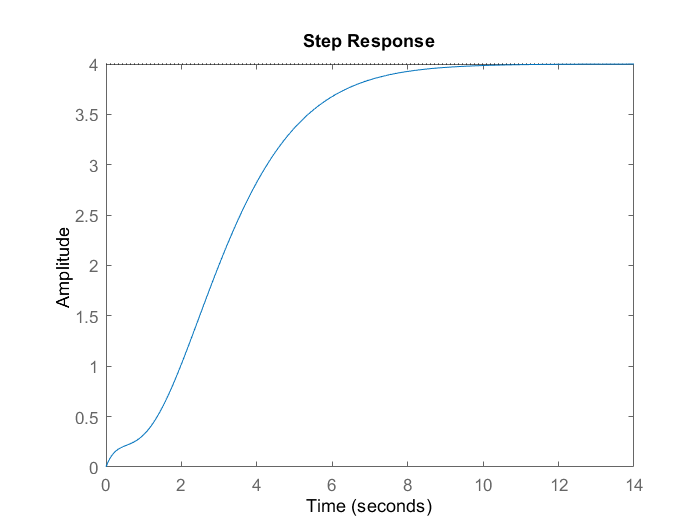

step(tf6)

- Strictly proper

- **no **initial undershoot

- **no** zero crossing

- **no **overshoot

- 0 positive zero of $G(s)$, 2 complex zeros

- 0 positive zero of $G(s)-G(\infty)$,2 complex zeros

- 0 positive zero of $G(s)-G(0)$,2 complex zeros

**4.B.**

Yes, it is possible for a linear dynamical system to exhibit bounded response for unbounded input.

Consider the transfer function 


$$G(s)=\frac{s}{s^2+4s+4}$$
 

when we provide a ramp function we'll get a bounded output.

figure
tf7=tf([1,0],[1,4,4])

tf7 =
 
        s
  -------------
  s^2 + 4 s + 4
 
Continuous-time transfer function.



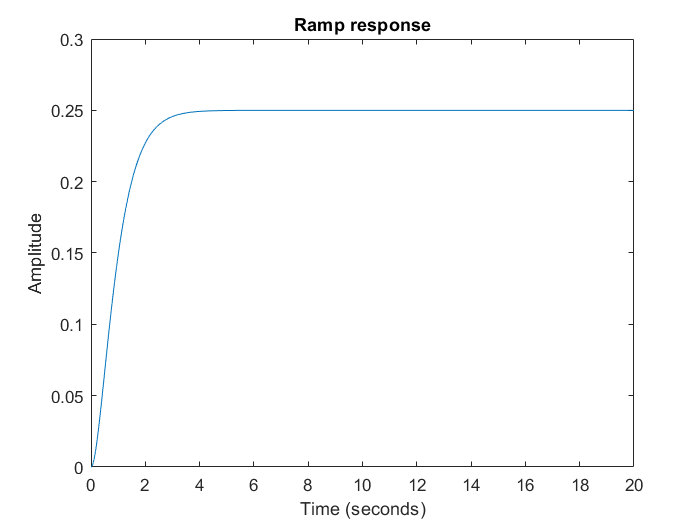

t=0:1e-4:20;
[Y,T]=lsim(tf7,t,t);
plot(T,Y)
title("Ramp response");
ylabel("Amplitude");
xlabel("Time (seconds)");

Hence we observe, for an unbounded ramp input we get a bounded response from a linear dynamical system.